## Approximation using Piecewise Bernstein Polynomials

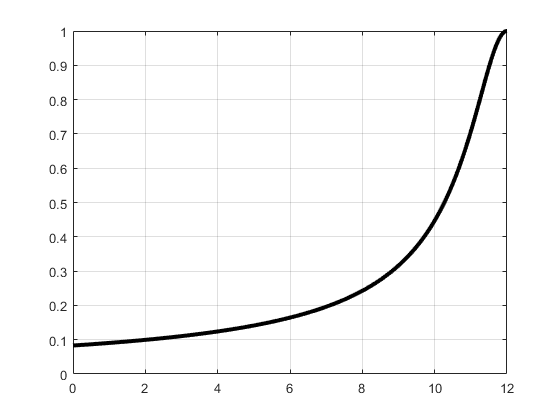

clear all

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Bernstein Approximation of smooth functions
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


N = 50; % Order of approximation (N+1 nodes)
M = 10;


%% Define the following functions
T = 12;
u1 = @(t) 1./(sqrt(1+(T-t).^2));
u2 = @(t) (T-t)./(sqrt(1+(T-t).^2));
% Plot the functions in [0,T]
t = 0:0.01:T;
u1figcomp = figure;
plot(t,u1(t),'LineWidth',3,'Color','k'); hold on
%set(gca,'fontsize', 26);
grid on

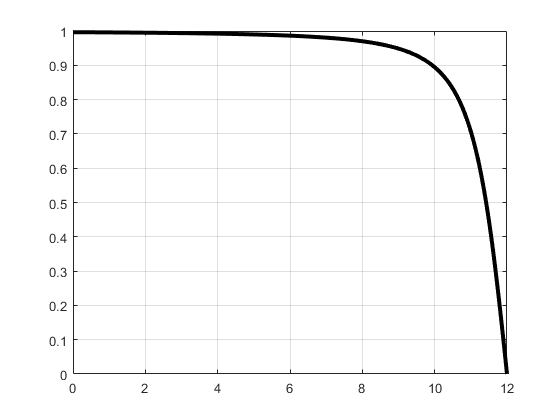

u2figcomp = figure;
plot(t,u2(t),'Linewidth',3,'Color','k'); hold on
grid on

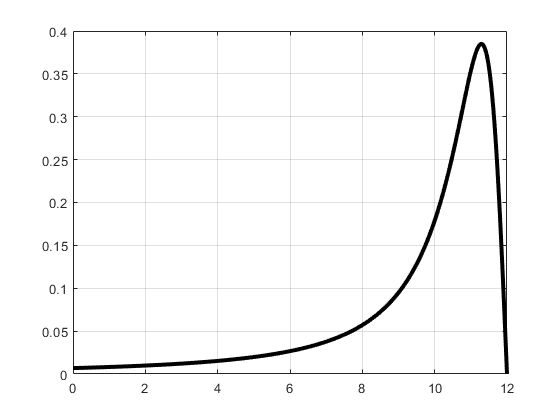

%set(gca,'fontsize', 26);


% Their derivatives are
u1dot = @(t) (T-t)./((T-t).^2+1).^(3/2);
u2dot = @(t) -1./(T^2-2*T*t+t.^2+1).^(3/2);
% Plot the derivatives in [0,T]
u1dotfigcomp = figure;
plot(t,u1dot(t),'Linewidth',3,'Color','k'); hold on
%set(gca,'fontsize', 26);
grid on

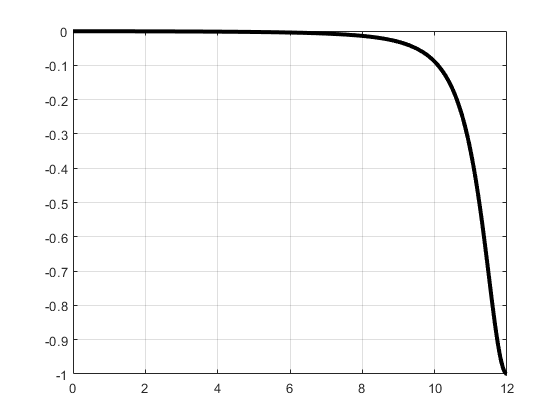

u2dotfigcomp = figure;
plot(t,u2dot(t),'Linewidth',3,'Color','k'); hold on
%set(gca,'fontsize', 26);
grid on


% Their integrals are
intu1 = asinh(T);
intu2 = sqrt(T^2+1)-1;

%% Compute Bern approx nodes/weights/Diff
tknots = linspace(0,T,M);
[tnodes,w,D] = PiecewiseBeBOT(N,tknots);

'PiecewiseBeBOT' is not found in the current folder or on the MATLAB path, but exists in:
    \\iowa.uiowa.edu\shared\Engineering\Home\vcichella\windowsdata\Desktop\LGL_PS Examples\BeBOT

Change the MATLAB current folder or add its folder to the MATLAB path.


%% Plot the function at the equidistant nodes
u1nodes = u1(tnodes);
u2nodes = u2(tnodes);
figure(u1figcomp)
plot(tnodes,u1nodes,'o','Linewidth',4); 
figure(u2figcomp)
plot(tnodes,u2nodes,'o','Linewidth',4); 




%% Compute the Piecewise Bernstein Polynomial at these nodes
u1N = PiecewiseBernsteinPoly(u1nodes,tknots,t);
u2N = PiecewiseBernsteinPoly(u2nodes,tknots,t);
figure(u1figcomp)
plot(t,u1N,'Linewidth',2,'Color','b'); 
figure(u2figcomp)
plot(t,u2N,'Linewidth',2,'Color','b'); 
%% Compute the derivative of Bernstein poly
u1nodes_dot = u1nodes*D;
u2nodes_dot = u2nodes*D;
u1Ndot = PiecewiseBernsteinPoly(u1nodes_dot,tknots,t);
u2Ndot = PiecewiseBernsteinPoly(u2nodes_dot,tknots,t);
figure(u1dotfigcomp)
plot(tnodes,u1nodes_dot,'o','Linewidth',4);
plot(t,u1Ndot,'Linewidth',2,'Color','b'); 
figure(u2dotfigcomp)
plot(tnodes,u2nodes_dot,'o','Linewidth',4); 
plot(t,u2Ndot,'Linewidth',2,'Color','b'); 




%% Compute the integral of Bernstein poly
intu1N = u1nodes*w;
intu2N = u2nodes*w;
% Compare to analytical answer
intu1;
intu2;




% Compare the integral of Bernstein approximation for different N
i = 0;
for N = 5:20
    i = i + 1;
    [tnodes,w,~] = PiecewiseBeBOT(N,tknots);
    u1nodes = u1(tnodes);
    u2nodes = u2(tnodes);
    intu1N(i) = u1nodes*w;
    intu2N(i) = u2nodes*w;
    order(i) = N;
end
figure
plot(order,intu1N,'Linewidth',2,'Color','b'); hold on
plot(order,intu1*ones(length(order),1),'Linewidth',2,'Color','k');
legend('numerical','analytical')
%set(gca,'fontsize', 26);
grid on
figure
plot(order,intu2N,'Linewidth',2,'Color','b'); hold on
plot(order,intu2*ones(length(order),1),'Linewidth',2,'Color','k');
legend('numerical','analytical')
%set(gca,'fontsize', 26);
grid on


















%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Bernstein Approximation of non-smooth functions
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


N = 4; % Order of approximation (N+1 nodes)




%% Define the following function
syms u(t)
T = 2;
u(t) =@(t) piecewise(t<=T/2, 1, T/2<t, -1);
t = 0:0.01:T;
uval = u(t);
figure
plot(t,uval,'Linewidth',2,'Color','k'); hold on
%set(gca,'fontsize', 26);
grid on


%% Compute Bern approx nodes/weights/Diff
tknots = linspace(0,T,5);
[tnodes,~,~] = PiecewiseBeBOT(N,tknots);


%% Plot the function at the equidistant nodes
unodes = u(tnodes);
plot(tnodes,unodes,'o','Linewidth',4); hold on




%% Compute the Bernstein Polynomial at these nodes
uN = PiecewiseBernsteinPoly(unodes,tknots,t);
plot(t,uN,'Linewidth',2,'Color','b'); 


















%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Lagrange approximation of non-smooth functions
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%% Plot the function on different figures
figure
plot(t,uval,'Linewidth',2,'Color','k'); hold on
%set(gca,'fontsize', 26);
grid on


%% Compute LGL nodes
[tnodes,~,~] = LGL_PS(N,T); % Compute tnodes,w,Diff in [0,T]


%% Plot the function at LGL nodes
unodes = u(tnodes);
plot(tnodes,unodes,'o','Linewidth',4);


%% Compute the Lagrange polynomial at these nodes
uN = LagrangePoly(unodes,tnodes,t);
plot(t,uN,'Linewidth',2,'Color','b'); 
